clc
clear 

s = tf('s');

K = 1; % Controller gain (Damping)

G = 1/(s^2+s+1); % Spring-Mass-Damper (SMD)
F = 1/(1+s/100); % Low Pass Filter (LPF)
P = 1/(1+s/10);  % Power Take-Off (PTO)
CL = feedback(P*G*F, K);

disp('Spring-Mass-Damper:')

Spring-Mass-Damper:


G

G =
 
       1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



disp('***************')

***************


disp(' ')


disp('Low-pass filter:')

Low-pass filter:


F

F =
 
    100
  -------
  s + 100
 
Continuous-time transfer function.



disp('***************')

***************


disp(' ')


disp('Power Take Off:')

Power Take Off:


P

P =
 
    10
  ------
  s + 10
 
Continuous-time transfer function.



disp('***************')

***************


disp(' ')


disp('Closed-Loop dynamics:')

Closed-Loop dynamics:


CL

CL =
 
                    1000
  ----------------------------------------
  s^4 + 111 s^3 + 1111 s^2 + 1110 s + 2000
 
Continuous-time transfer function.



disp('***************')

***************


disp(' ')

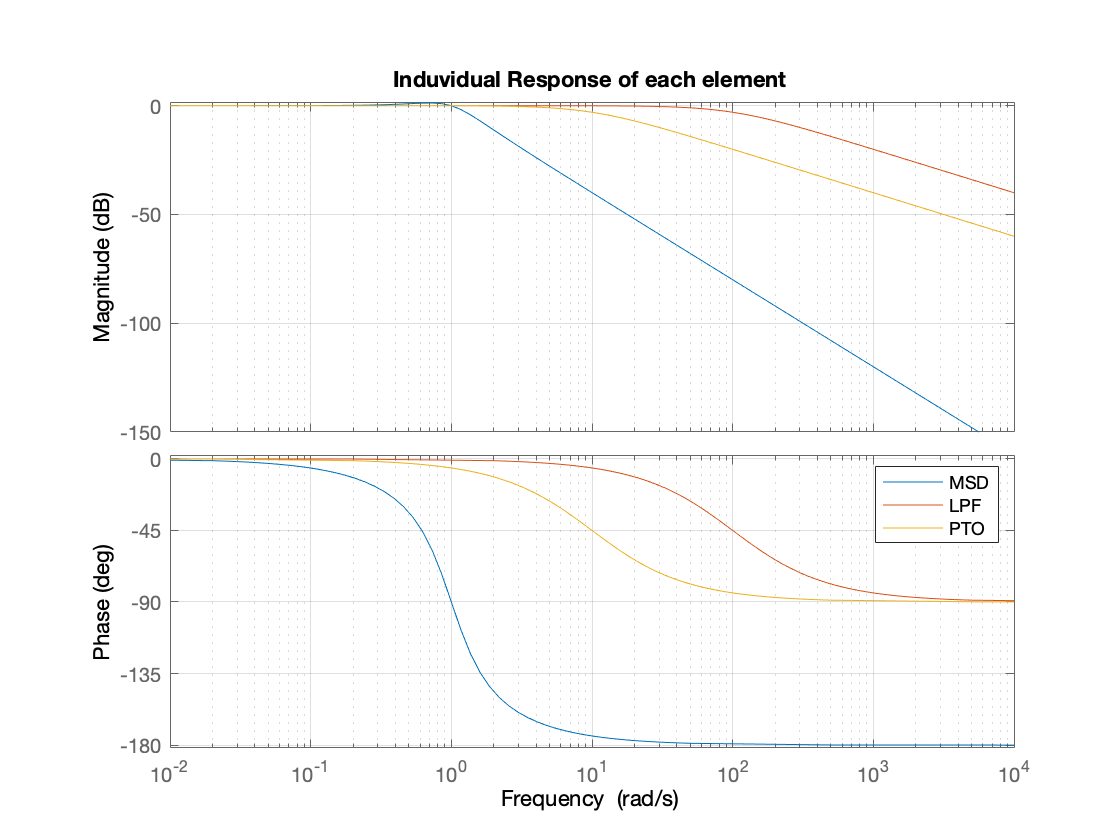


figure
bode(G, F, P)
grid on
legend('MSD', 'LPF', 'PTO')
title('Induvidual Response of each element')

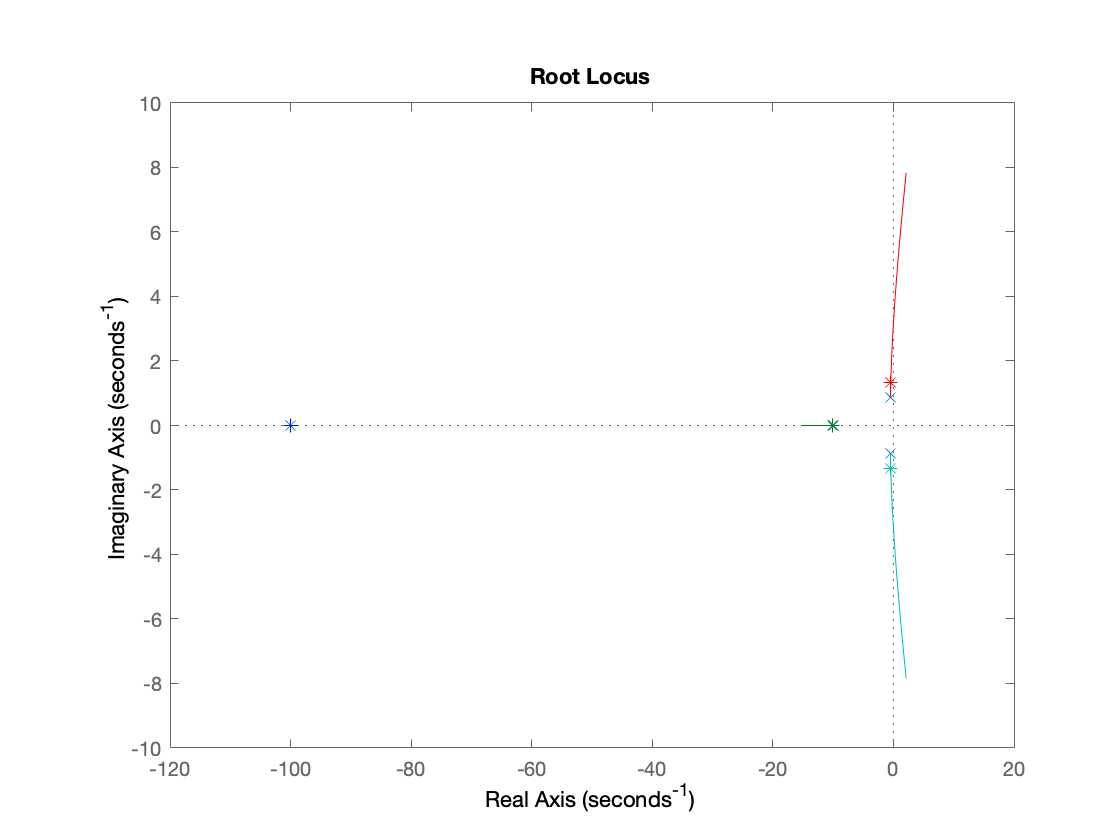



figure
rlocus(P*G*F, K, '*')
hold on
rlocus(P *G*F, 0:100)
hold off

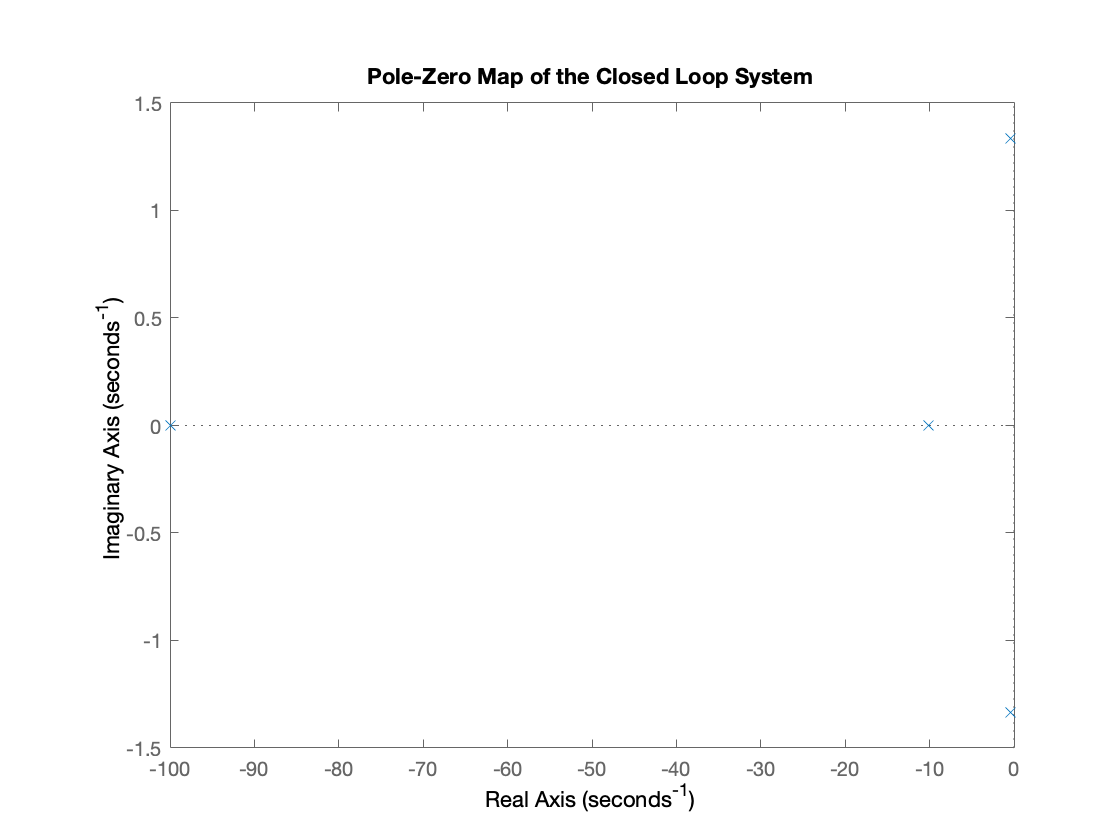



figure
pzmap(CL)
title('Pole-Zero Map of the Closed Loop System')

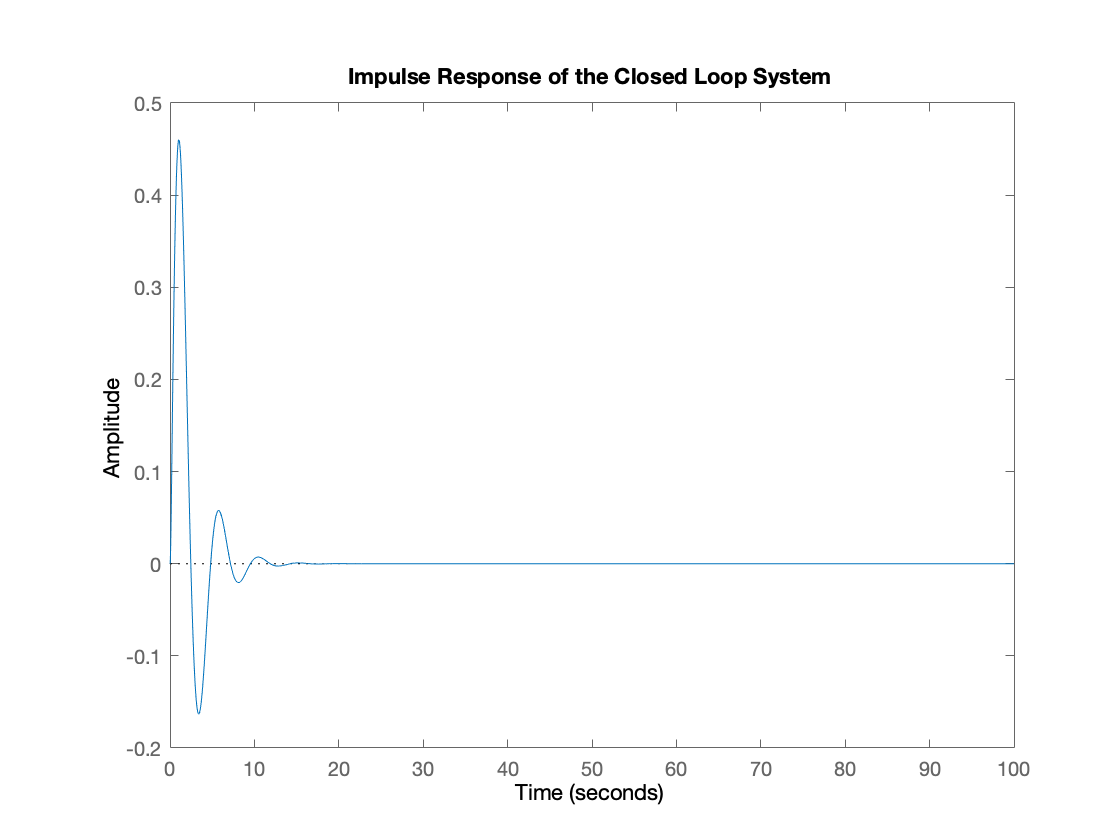



figure
impulse(CL, 100)
title('Impulse Response of the Closed Loop System')